% J.Williams
% University of Wisconsin-Madison
% EPD629: Powertrain Systems and Controls
% Assignement 02
% 2022-01-31

% Link to textbook end of chapter problems:
% https://bcs.wiley.com/he-bcs/Books?action=mininav&bcsId=11568&itemId=1119474221&assetId=473646&resourceId=45905&newwindow=true

% Homework assignment (copy/pasted) below:
% % This homework assignment is to create a vehicle longitudinal dynamic model for a truck.  Operation of the truck will be simulated in Simulink.  The free body diagram for the truck is shown below.   
% %  The governing equations for this model are as follows:
% % 	Faero = ½  Cd  A    v2
% % 	Frolling = Cr  m  g
% %  	Fincline = m  g  sin()
% % 	∑ F = m  a
% % 	a = (Ftrac - Faero - Frolling - Fincline) / m
% % 	v =  a dt
% % 	x =  v dt
% % In this model tractive force is the input.  Vehicle speed and position are the outputs.
% % 
% % 1)	Create an initialization script with the following commands (1 points)
% % clear
% % close all
% % clc
% %  
% % % Ambient Conditions
% %  
% % AmbientPress_kPa = 100;
% % AmbientTemp_C = 20;
% %  
% % % Constants
% %  
% % AirGasConstant_kJpkgK = 0.278;
% % CelsiusToKelvinConstant = 273.15;
% % GravitationalAccel_mps2 = 9.8067;
% %  
% % % Road Grade
% %  
% % PitchAngleData_deg = [2 2];
% % PitchAnglePositionBP_m = [0 1e6];
% %  
% % % Vehicle
% %  
% % VehicleMass_kg = 30000;
% % AeroArea_m2 = 10;
% % AeroDragCoef = 0.6;
% % RollingDragCoef = 0.005;
% % 
% % 2)	In Simulink create the following subsystem model for Road Load (2 points)
% % 
% %  
% % 
% % Configure the pitch angle table lookup as shown below.
% %  
% %  
% % 
% % 3)	In Simulink create the following subsystem model for Vehicle Dynamics (2 points)
% % 
% %  
% % 
% % Configure the two Integrator blocks as shown below.
% % 
% %   Vehicle Speed				     Vehicle Position
% %  
% % 
% % 4)	Attach the two subsystems as shown below. (1 point)
% %  
% % Configure the Step bock as shown below.
% % 
% %  
% % 
% % 
% % 5)	Set the Stop Time as 2000 seconds. Run the simulation. Verify that your results are the same as the following using the Scope. (1 point)
% %  
% % 
% % 6)	Complete chapter 1 textbook problem 13a, 13b, and 13c. (3 points)
% % 
% % 7)	Complete chapter 1 textbook problem 14a, 14b, and 14c. (3 points)

% Q1:
close all;
clear; clc;
fprintf("\nQ1\n")


Q1



% Ambient Conditions
AmbientPress_kPa = 100; % Ambient air pressure
AmbientTemp_C = 20; % Ambient air temperature
 
% Constants
AirGasConstant_kJpkgK = 0.278; % Gas constant of air
CelsiusToKelvinConstant = 273.15; 
GravitationalAccel_mps2 = 9.8067; % Acceleration due to gravity
 
% Road Grade
PitchAngleData_deg = [2 2]; 
PitchAnglePositionBP_m = [0 1e6];
 
% Vehicle
VehicleMass_kg = 30000; % Vehicle mass
AeroArea_m2 = 10; % Frontal Area of vehicle
AeroDragCoef = 0.6; % Vehicle aerodynamic drag coefficient
RollingDragCoef = 0.005; % Vehicle rolling resistance coefficient

% % Formulas
% F_sum = m*a 
% a = (F_trac - F_aero - F_rolling - F_incline)/m 
% v = integral(a dt)
% F_aero = (1/2)*C_d*A*rho*v.^2 % Aerodynamic drag resistance force
% F_rolling = C_r*m*g % Rolling resistance force
% F_incline = m*g_*sin(theta) % Force to overcome component of gravity on hill









%Q2 (6):
%From textbook:
%1-13:
% % Given the electric network shown in Figure P1.5.
% % [Review]
% % a. Write the differential equation for the network if
% % v(t) = u(t), a unit step.
% % b. Solve the differential equation for the current, i(t), if
% % there is no initial energy in the network.
% % c. Make a plot of your solution if R/L=1.
%
%Attempt:
% If V_source-V_resistor-V_inductor=0
% V_source = V_resistor + V_inductor
% V_source = i*R + L*(di/dt)
% % % dV/dt = R*(di/dt) + L*(di/dt)^2 %%% Part a
% % % dV/dt = (R+L*(di/dt))*(di/dt)
% L*(di/dt) = V_source - i*R
% di/dt = (V_source - i*R)/L
% di/(V_source - i*R) = dt/L
% Integrate
% -ln(V - i*R)/R = 1/L*t + Constant
% solving for constant:
% Constant = -ln(V - i*R)/R - 1/L*t
% if i(0)=0 IE current is initially zero
% Constant = -ln(V)/R
% then
% -ln(V - i*R)/R = (1/L)*t -ln(V)/R
% -ln(V - i*R) = (R/L)*t - ln(V)
% ln((V - i*R)/(V) = -(R/L)*t
% (V - i*R)/V = e^(-(R/L)/t)
% 1 - i*R/V = e^(-(R/L)/t)
% -(R/V)*i = e^(-(R/L)/t) - 1
% i =  (-1 + e^(-(R/L)/t))/(-R/V)
% i = (1 + e^(-(R/L)/t)))*(V/R)

% clear;
% not clearing due to needing for simulink model, and no conflicting variables

% Plot a solution
R = 110; % Ohms
V = 14.5; % Volts
Ratio_RL = 1; % R/L
L = R/Ratio_RL; % Henries (Inductance)
t = linspace(0,20,1000) % Time vector

t =          0    0.0200    0.0400    0.0601    0.0801    0.1001    0.1201    0.1401    0.1602    0.1802    0.2002    0.2202    0.2402    0.2603    0.2803    0.3003    0.3203    0.3403    0.3604    0.3804    0.4004    0.4204    0.4404    0.4605    0.4805    0.5005    0.5205    0.5405    0.5606    0.5806    0.6006    0.6206    0.6406    0.6607    0.6807    0.7007    0.7207    0.7407    0.7608    0.7808    0.8008    0.8208    0.8408    0.8609    0.8809    0.9009    0.9209    0.9409    0.9610    0.9810


i = (1 + exp(-(R/L)./t)).*(V/R) % Current vector

i =     0.1318    0.1318    0.1318    0.1318    0.1318    0.1318    0.1319    0.1319    0.1321    0.1323    0.1327    0.1332    0.1339    0.1346    0.1355    0.1365    0.1376    0.1388    0.1400    0.1413    0.1427    0.1440    0.1454    0.1468    0.1483    0.1497    0.1511    0.1525    0.1540    0.1554    0.1568    0.1581    0.1595    0.1608    0.1622    0.1635    0.1647    0.1660    0.1672    0.1684    0.1696    0.1708    0.1719    0.1731    0.1742    0.1753    0.1763    0.1774    0.1784    0.1794


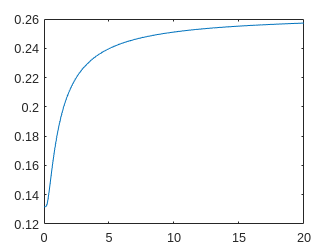

figure
plot(t, i) % Plot current vs time





%Q3 (7)
% From textbook:
%1-14:
% % Repeat Problem 13 using the network shown in
% % Figure P1.6. Assume R=1Ω, L=0.5H, and 1/LC=16.

% Attempt:
% If V_source - V_resistor - V_inductor - V_capacitor = 0
% q is charge ; i = dq/dt
% V_source = V_resistor + V_inductor + V_capacitor
% V(t) = i*R + L(di/dt) + q/C
% q/C can be expressed as (1/C)*int[i dtau,0,t]
% V(t) = i*R + L(di/dt) + (1/C)*int[i dtau,0,t]
% V(t) = i*(R/L) + (di/dt) + (1/(L*C))*int[i dtau,0,t]
% at time t=0, say V(0) = 0 (Homogenous portion)
% 0 = i*(R/L) + (di/dt) + (1/(L*C))*int[i dtau,0,t]
% 0 = (di/dt) + i*(R/L) + (1/(L*C))*int[i dtau,0,t]
% Differentiate with resepect to t,
% 0 = (d^2i/dt^2) + (R/L)*(di/dt) + (1/(L*C))*i
% The 'auxillary equation' is then: m^2 + (R/L)*m - (!/(L*C))=0
% aux_coefficients = [1, R/L, 1/(L*C)]
aux_coefficients = [1, R/L, 16]

aux_coefficients =      1     1    16


roots(aux_coefficients)

ans =   -0.5000 + 3.9686i
  -0.5000 - 3.9686i


% This is 'Scenario 3', where roots are complex
% General solution for Scenario 3 is:
% y = e^(alpha*x)*(A*cos(beta*x)+B*sin(beta*x))




% Previous work discarded below:
% V(t) = i*R + L(di//dt) + q/C
%%
% V(t) = L(di//dt) + i*R + q/C
% dV(t)/dt = L(d^2i/dt^2) + R*(di/dt) + (1/C)*dq/dt
% dV(t)/dt = L(d^2i/dt^2) + R*(di/dt) + (1/C)*i
% (1/L)*(dV(t)/dt) = d^2i/dt^2 + (R/L)*(di/dt) + (1/(L*C))*i
% Must find natural response and forced response to get total response
% For natural response, say V(t) = 0
% Initial conditions i(o) = 0; di/dt(0) = 0
% Assume i(t) = A*e^(s*t)     IE i(t) = A*exp(s*t)
%%
% Characteristic equation
% s^2 + (R/L)*s + 1/(L*C) = 0
% Roots are:
% s = (-1/2)*(R/L) +/- ((R/(2*L))^2-1/(L*C))^(1/2)
% Recall i(t) = A*exp(s*t)
% 
% Since i = dq/dt, then
% V(t) = (dq/dt)*R + L*(d^2q/dt^2) + q/C
% V(t) = L*(d^2q/dt^2) + (dq/dt)*R + q/C
% V(t)/L = (d^2q/dt^2) + (R/L)*(dq/dt) + (1/(C*L))*q




